# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9996
    0.9996
    0.9020
    0.9020
    0.9271
    0.9271
    1.0000
    0.9773
    0.9538
    0.8508
    0.8508
    0.9480
    0.8070
    0.8070
    0.8761
    0.8761
    0.9074
    0.7490
    0.7490
    0.8854
    0.8671
    0.7350
    0.7350
    0.7567
    0.7553
    0.7553
    0.8189
    0.7938
    0.6193
    0.6193
    0.7618
    0.7079
    0.6544
    0.6372
    0.6425
    0.6744
    0.6744
    0.6020
    0.6060
    0.5049
    0.4719
    0.4719
    0.5112
    0.4492
    0.4866
    0.6322
    0.6322
    0.4876
    0.3483
    0.3483
    0.5551
    0.5551
    0.4222
    0.3204
    0.3204
    0.3263
    0.3087
    0.2773
    0.2773
    0.3040
    0.2707
    0.2707
    0

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

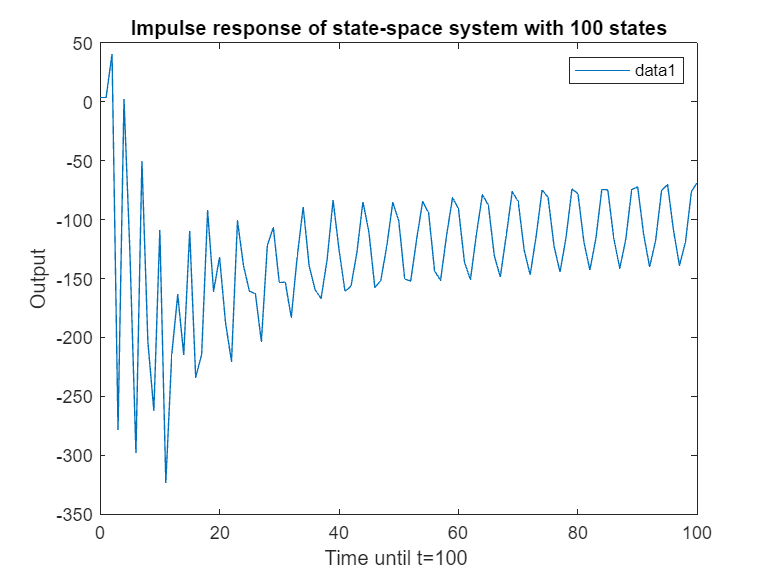

maxTime = 100;

figure;
dssplot(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a large enough T the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 4;
inputnum = 4;
maxTime = 100;
input = [2;1;2;3];


state_space = drss(statenum,outputnum,inputnum)

state_space =
 
  A = 
                x1         x2         x3         x4         x5         x6         x7         x8         x9        x10        x11        x12        x13        x14        x15        x16        x17        x18        x19        x20        x21        x22        x23        x24        x25        x26        x27        x28        x29        x30        x31        x32        x33        x34        x35        x36        x37        x38        x39        x40        x41        x42        x43        x44        x45        x46        x47        x48        x49        x50        x51        x52        x53        x54        x55        x56        x57        x58        x59        x60        x61        x62        x63        x64        x65        x66        x67        x68        x69        x70        x71        x72        x73        x74        x75        x76        x77        x78        x79        x80        x81        x82        x83        x84        x85        x86        x87        x88  

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 4"
    "Number of outputs: 4"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:4"  
    "C_rows:4"      "C_cols:100"
    "D_rows:4"      "D_cols:4"  

Max absolute eigen value: 0.99925
Eigen values of A: 
    0.9993
    0.9993
    0.9285
    0.9285
    0.9566
    0.9566
    0.9598
    0.8798
    0.8798
    0.7230
    0.7230
    0.7455
    0.7455
    0.7476
    0.7476
    0.7151
    0.9831
    0.6399
    0.6399
    0.6655
    0.6451
    0.5946
    0.5946
    0.9310
    0.9274
    0.6359
    0.6223
    0.6213
    0.5392
    0.5392
    0.4455
    0.4455
    0.4549
    0.4549
    0.8371
    0.4430
    0.4430
    0.7036
    0.7036
    0.5047
    0.5059
    0.7899
    0.7223
    0.7223
    0.7862
    0.7135
    0.7431
    0.7379
    0.6973
    0.6679
    0.4995
    0.4995
    0.7684
    0.6265
    0.3846
    0.3820
    0.3624
    0.5762
    0.5485
    0.5257
    0.4637
    0.4637

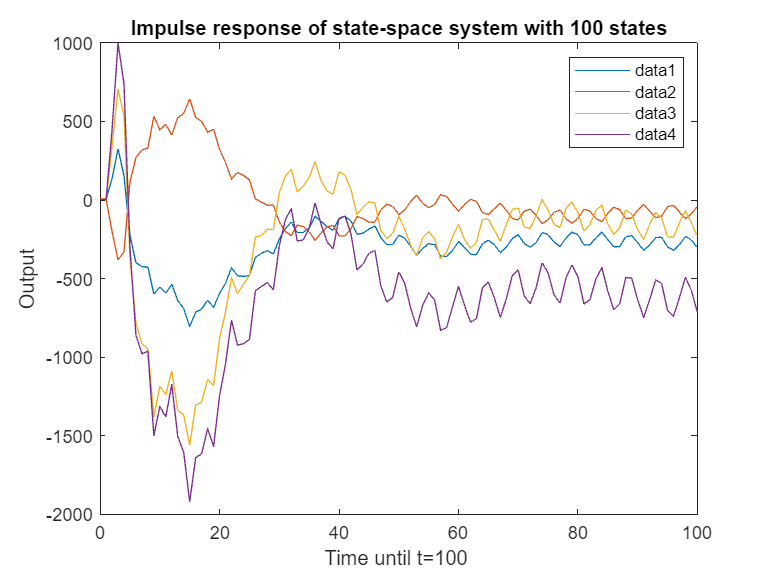

figure;
dssplot(state_space,maxTime,input);

Lets plot the trajectory of the impulse response with the old input and some new input.

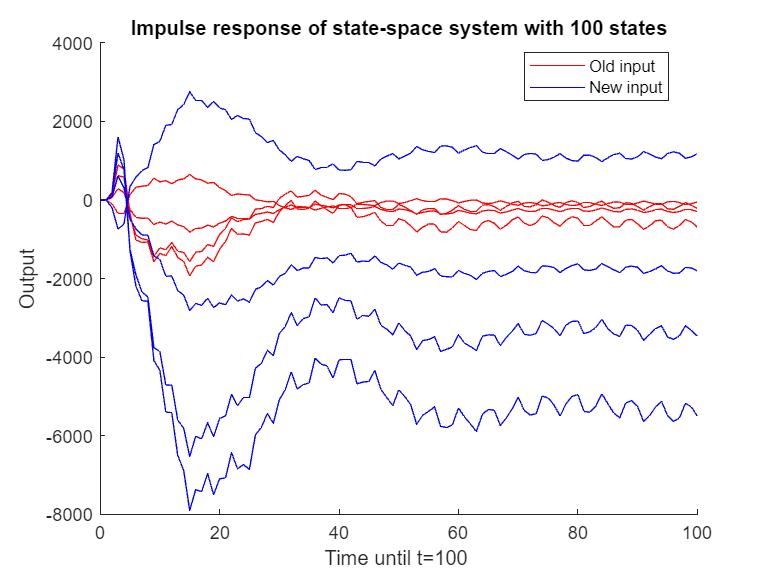

figure;
hold on
f1 = dssplot(state_space,maxTime,input);
f2 = dssplot(state_space,maxTime,[2;1;5;6]);
set(f1, 'Color', 'r');
set(f2, 'Color', 'b');
legend([f1(1), f2(1)], {'Old input', 'New input'}, 'Location', 'best');
hold off;

## Experimenting with Hankel Matrices

Now we're going to experiment with hankel matrices and show how it is relevant to time-series data.  Firstly, we create a drss and with a single in- and output and random initial conditions. We then convert the output to a hankel matrix.

input = 2;
inputnum = 1;
outputnum = 1; 
statenum = 3;
maxTime = 50;

dss = drss(statenum, outputnum, inputnum)

dss =
 
  A = 
            x1       x2       x3
   x1    1.677   0.7356   0.7807
   x2   -3.804   -1.915   -1.158
   x3   -1.581  -0.4875   -1.186
 
  B = 
            u1
   x1    1.396
   x2  -0.3093
   x3    3.177
 
  C = 
           x1      x2      x3
   y1  0.6018   1.369  -1.045
 
  D = 
            u1
   y1  -0.9083
 
Sample time: unspecified
Discrete-time state-space model.


[x,y] = dsssim(dss,maxTime,input)

x =     0.2883    3.8642   11.2020    6.4598    9.1593    7.6812    8.4541    8.0801    8.2344    8.1962    8.1772    8.2208    8.1700    8.2193    8.1753    8.2127    8.1819    8.2068    8.1870    8.2025    8.1904    8.1998    8.1926    8.1981    8.1939    8.1971    8.1947    8.1965    8.1951    8.1962    8.1954    8.1960    8.1955    8.1959    8.1956    8.1958    8.1957    8.1958    8.1957    8.1958    8.1957    8.1957    8.1957    8.1957    8.1957    8.1957    8.1957    8.1957    8.1957    8.1957
    0.6428   -3.1175  -15.6124   -7.9508  -12.0199  -10.0312  -10.8688  -10.6422  -10.5651  -10.7752  -10.5236  -10.7706  -10.5491  -10.7378  -10.5821  -10.7079  -10.6078  -10.6865  -10.6251  -10.6727  -10.6360  -10.6642  -10.6426  -10.6591  -10.6465  -10.6561  -10.6488  -10.6544  -10.6501  -10.6534  -10.6509  -10.6528  -10.6514  -10.6524  -10.6516  -10.6522  -10.6518  -10.6521  -10.6519  -10.6521  -10.6519  -10.6520  -10.6519  -10.6520  -10.6520  -10.6520  -10.6520  -10.6520  -10.6520  -10

y =     0.8984   -0.9183   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846  -10.7946  -10.7870  -10.7928  -10.7884  -10.7917  -10.7892  -10.7911  -10.7896  -10.7907  -10.7899  -10.7905  -10.7901  -10.7904  -10.7902  -10.7904  -10.7902  -10.7903  -10.7902  -10.7903  -10.7903  -10.7903  -10.7903  -10.7903  -10.7903


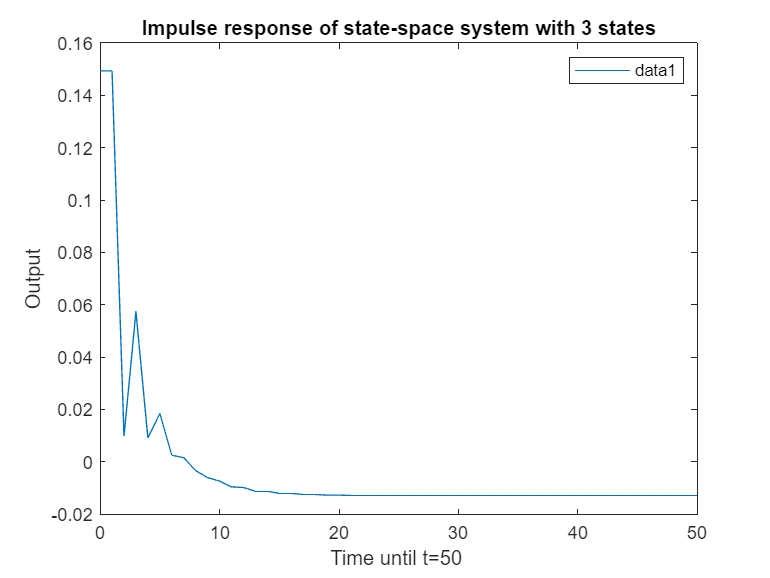

dssplot(dss,maxTime,input);

delta = 26

delta = 26

c = y(1,1:delta)

c =     0.8984   -0.9183   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846


r =y(1,delta:size(y,2))

r =   -10.7846  -10.7946  -10.7870  -10.7928  -10.7884  -10.7917  -10.7892  -10.7911  -10.7896  -10.7907  -10.7899  -10.7905  -10.7901  -10.7904  -10.7902  -10.7904  -10.7902  -10.7903  -10.7902  -10.7903  -10.7903  -10.7903  -10.7903  -10.7903  -10.7903  -10.7903


H = hankel(c,r)

H =     0.8984   -0.9183   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846
   -0.9183   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846  -10.7946
   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846  -10.7946  -10.7870
  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -

H = hankelizeM(y,26)

H =     0.8984   -0.9183   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846
   -0.9183   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846  -10.7946
   -9.4126  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -10.7978  -10.7846  -10.7946  -10.7870
  -11.5830  -10.6644  -10.5779  -11.1398  -10.4104  -11.1483  -10.4763  -11.0542  -10.5744  -10.9635  -10.6531  -10.8978  -10.7066  -10.8550  -10.7404  -10.8286  -10.7610  -10.8127  -10.7732  -10.8033  -10.7804  -

## Experimenting with Hankel Matrix Completion